clc;
close all;
clear variables;

sim_file_name = 'promena_topologije_kontrolera_sim';
open_system(sim_file_name)

K_pracenje_ref = kontroler_pracenje_reference_foo();
K_poremecaj = kontroler_potiskivanje_poremecaja_foo(); % ne koristiti

[K_zno, K_zno_mod] = ziegler_nichols_odskocni_foo();
[K_znf, K_znf_mod] = ziegler_nichols_frekvencijski_foo();

[L, R, C, E, x2e] = nominalni_parametri();
[G, A, B, H, ue] = linearizacija();
s = tf('s');

Tt = 1e-3; % s

sigma = 0.05 * abs(x2e);

sim_duration = 1.5; % sec
time_step = 1e-4; % sec

t_ref_stepdown1 = 0.4*sim_duration;
amp_ref_stepdown1 = -0.05 * abs(x2e);

t_ref_stepup1 = 0.6*sim_duration;
amp_ref_stepup1 = 0.05 * abs(x2e);

t_ref_stepdown2 = 0.8*sim_duration;
amp_ref_stepdown2 = 0;

t_poremecaj = 0.5*sim_duration;
amp_poremecaj = 0.1*E;

K = [K_pracenje_ref, K_zno, K_znf];
K_name = {"praćenje" + newline + "reference", ...
    "ZN" + newline + "odskočni odziv",...
    "ZN" + newline + "frekvencijski odziv"};

## Kontroler u formi funkcije prenosa

kontroler_pik = 1;
for i = 1:length(K)
    [Kp, Ti, Td, Tf] = PID_oblik_foo(K(i));
    Kontroler = minreal(Kp*(1 +1/Ti/s + Td*s/(Tf*s + 1)));
    
    out(i) = sim(sim_file_name);
end

close all
for i = 1:length(K)        

Zuta linija je K_zno koji se strašno navije na početku i uopšte ne radi u ovoj formi

    my_title = "Poredjenje odziva" + "- funkcija prenosa";
    figure(1)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', 'best')
    title(my_title)
    xlabel('t [s]')
    ylabel('x2 [V]')
    

#### Dovodjenje u nominalni režim

    my_subtitle = " - dovodjenje u nominalni režim";
    figure(2)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', 'best')
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0 sim_duration / 5])
    

#### Praćenje reference u blizini nominalnog režima

    my_subtitle = " - Praćenje reference u blizini nominalnog režima";
    figure(3)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([x2e * 1.07 x2e * 0.93])
    

#### Upravljanje sa saturacijom

    my_subtitle = " - upravljanje sa saturacijom";
    figure(4)
    hold on
    if i == 1
        plot(ue, 'DisplayName','ref')
    end
    plot(out(i).u_sat, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('duty cycle')
    % xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([0 1.05])
    

#### Potiskivanje poremećaja

    my_subtitle = " - potiskivanje poremećaja";
    figure(5)
    hold on
    if i == 1
        plot(x2e, 'DisplayName','ref')
    end
    plot(out(i).x2_poremecaj, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([x2e * 1.2 x2e * 0.8])

#### Fazni portret

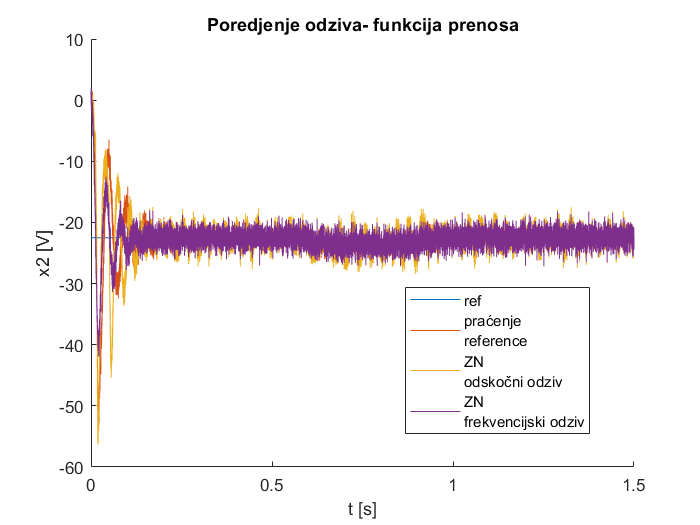

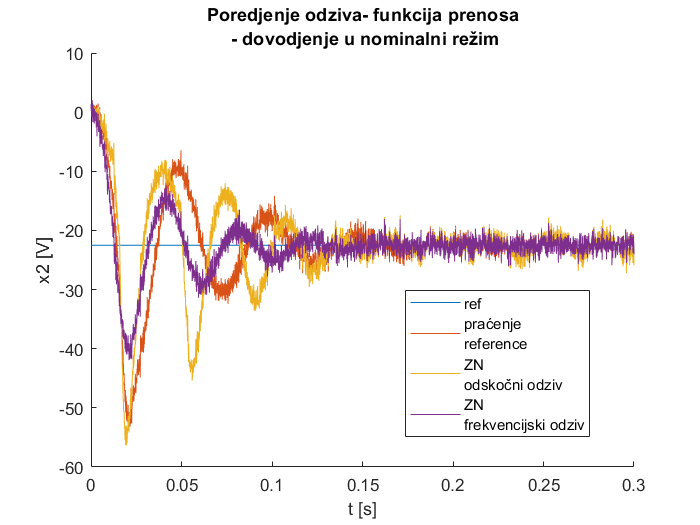

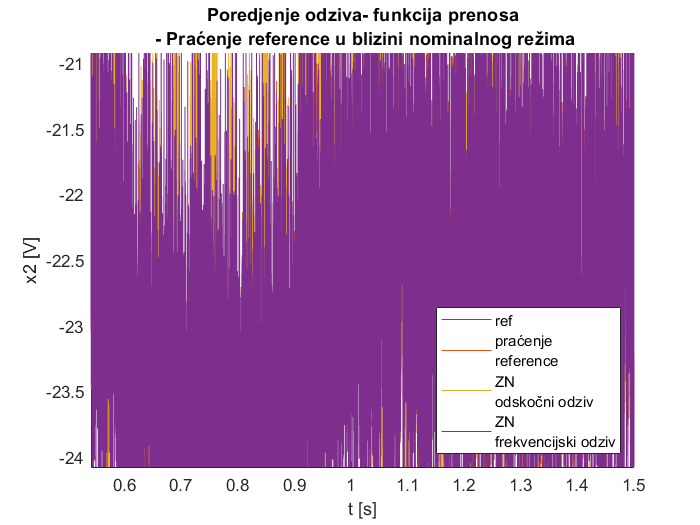

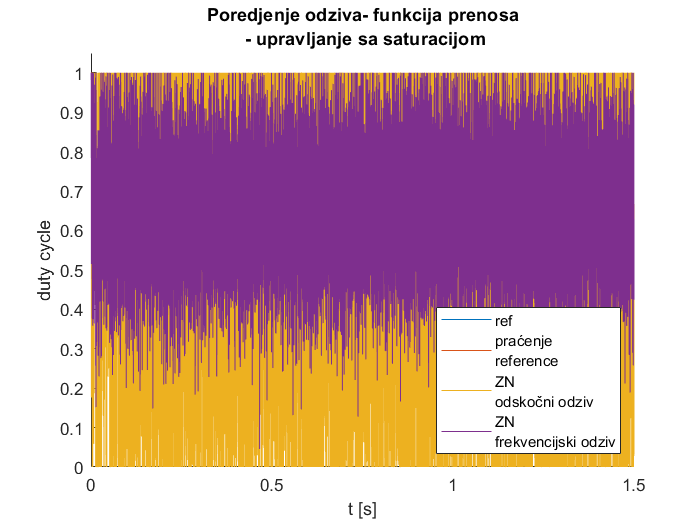

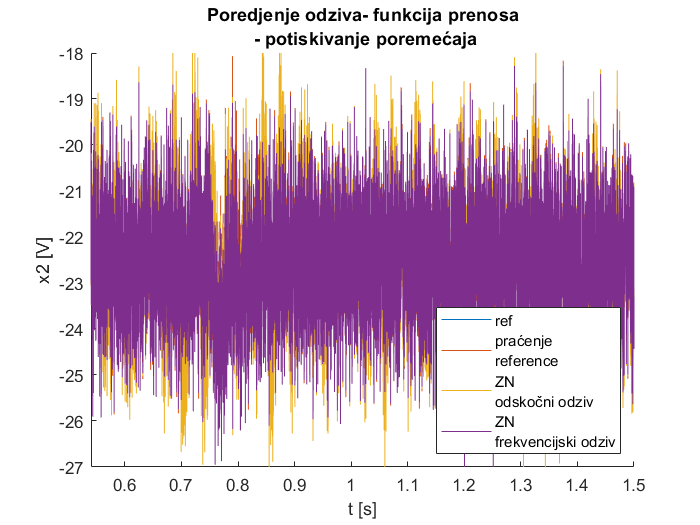

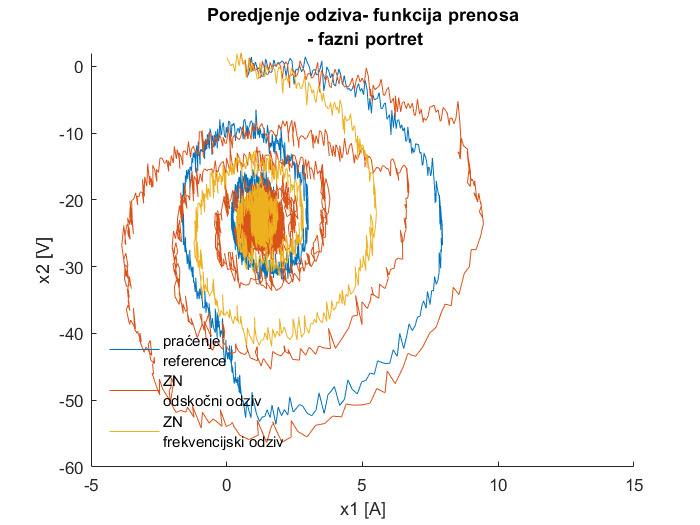

     my_subtitle = " - fazni portret";
    figure(6) 
    hold on
    plot(out(i).x1.Data,out(i).x2.Data,'DisplayName', K_name{i});
    legend('Location', "southwest",'Box','off')
    title(my_title + newline + my_subtitle)
    xlabel('x1 [A]')
    ylabel('x2 [V]')
      xlim([-5, 15])
     ylim([-60 2]) 
end

## Kontroler u formi PID-a sa anti-windupom

kontroler_pik = 2;
for i = 1:length(K)
    [Kp, Ti, Td, Tf] = PID_oblik_foo(K(i));
    Kontroler = minreal(Kp*(1 +1/Ti/s + Td*s/(Tf*s + 1)));
    
    out(i) = sim(sim_file_name);
end

close all
for i = 1:length(K)   

    my_title = "Poredjenje odziva" + "- anti-windup";
    figure(1)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', 'best')
    title(my_title)
    xlabel('t [s]')
    ylabel('x2 [V]')
    

#### Dovodjenje u nominalni režim

    my_subtitle = " - dovodjenje u nominalni režim";
    figure(2)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', 'best')
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0 sim_duration / 5])
    

#### Praćenje reference u blizini nominalnog režima

    my_subtitle = " - Praćenje reference u blizini nominalnog režima";
    figure(3)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([x2e * 1.07 x2e * 0.93])
    

#### Upravljanje sa saturacijom

    my_subtitle = " - upravljanje sa saturacijom";
    figure(4)
    hold on
    if i == 1
        plot(ue, 'DisplayName','ref')
    end
    plot(out(i).u_sat, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('duty cycle')
    % xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([0 1.05])
    

#### Potiskivanje poremećaja

    my_subtitle = " - potiskivanje poremećaja";
    figure(5)
    hold on
    if i == 1
        plot(x2e, 'DisplayName','ref')
    end
    plot(out(i).x2_poremecaj, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([x2e * 1.2 x2e * 0.8])

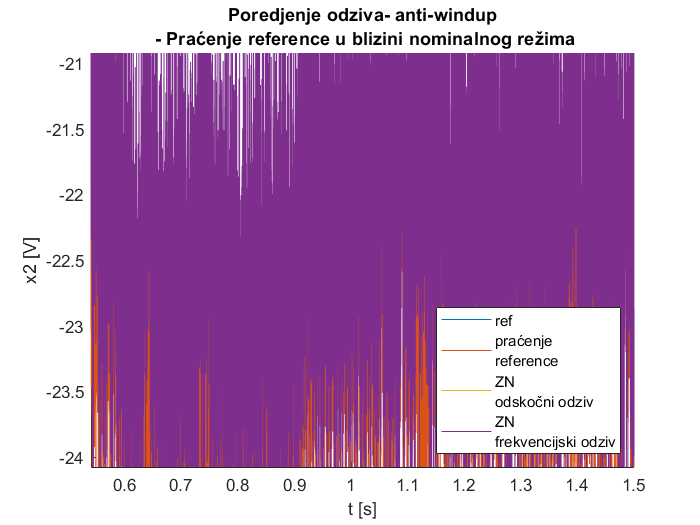

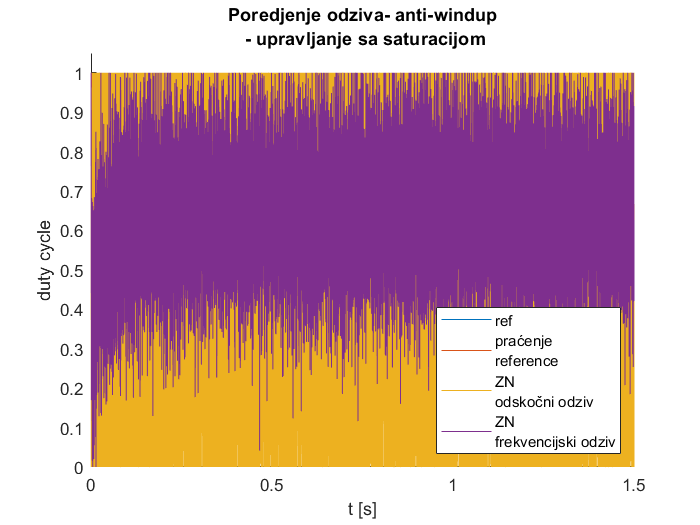

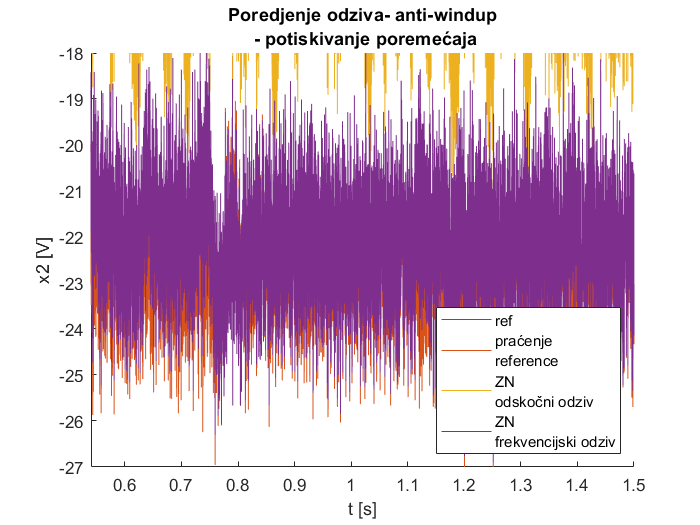

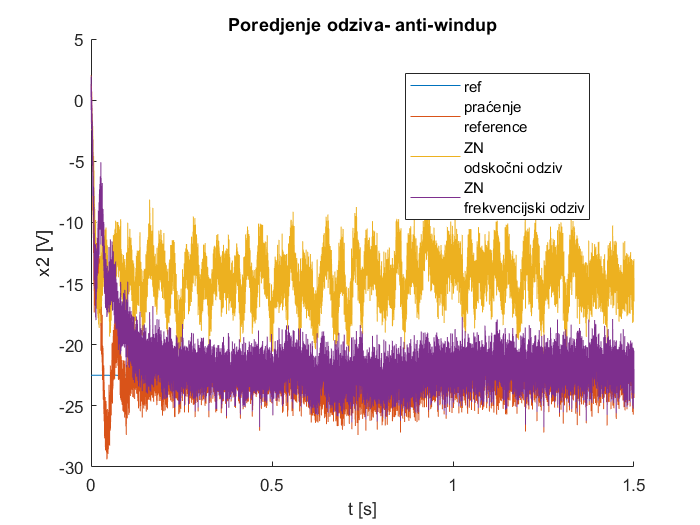

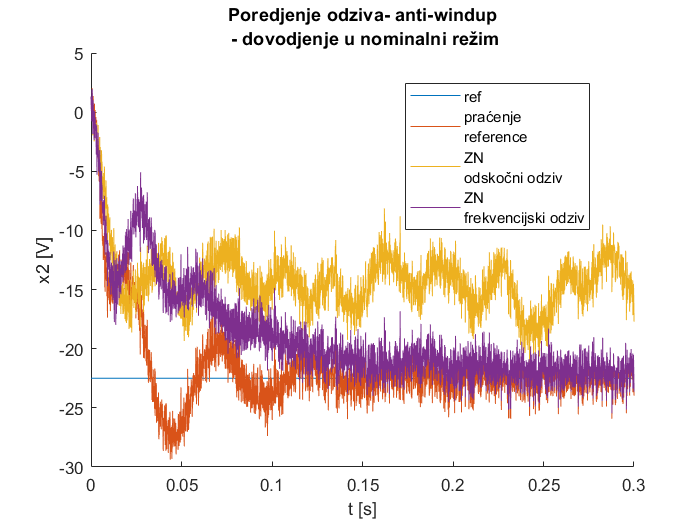

end

## Kontroler u formi PID-a sa anti-windupom + izmešteno D dejstvo

kontroler_pik = 3;
for i = 1:length(K)
    [Kp, Ti, Td, Tf] = PID_oblik_foo(K(i));
    Kontroler = minreal(Kp*(1 +1/Ti/s + Td*s/(Tf*s + 1)));
    
    out(i) = sim(sim_file_name);
end

close all
for i = 1:length(K)   

    my_title = "Poredjenje odziva" + "- anti-windup + izmešteno D dejstvo";
    figure(1)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', 'best')
    title(my_title)
    xlabel('t [s]')
    ylabel('x2 [V]')
    

#### Dovodjenje u nominalni režim

    my_subtitle = " - dovodjenje u nominalni režim";
    figure(2)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', 'best')
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0 sim_duration / 5])
    

#### Praćenje reference u blizini nominalnog režima

    my_subtitle = " - Praćenje reference u blizini nominalnog režima";
    figure(3)
    hold on
    if i == 1
        plot(out(i).referenca, 'DisplayName','ref')
    end
    plot(out(i).x2, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([x2e * 1.07 x2e * 0.93])
    

#### Upravljanje sa saturacijom

    my_subtitle = " - upravljanje sa saturacijom";
    figure(4)
    hold on
    if i == 1
        plot(ue, 'DisplayName','ref')
    end
    plot(out(i).u_sat, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('duty cycle')
    % xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([0 1.05])
    

#### Potiskivanje poremećaja

    my_subtitle = " - potiskivanje poremećaja";
    figure(5)
    hold on
    if i == 1
        plot(x2e, 'DisplayName','ref')
    end
    plot(out(i).x2_poremecaj, 'DisplayName', K_name{i})
    
    legend('Location', "southeast")
    title(my_title + newline + my_subtitle)
    xlabel('t [s]')
    ylabel('x2 [V]')
    xlim([0.9 * t_ref_stepdown1, sim_duration])
    ylim([x2e * 1.2 x2e * 0.8])

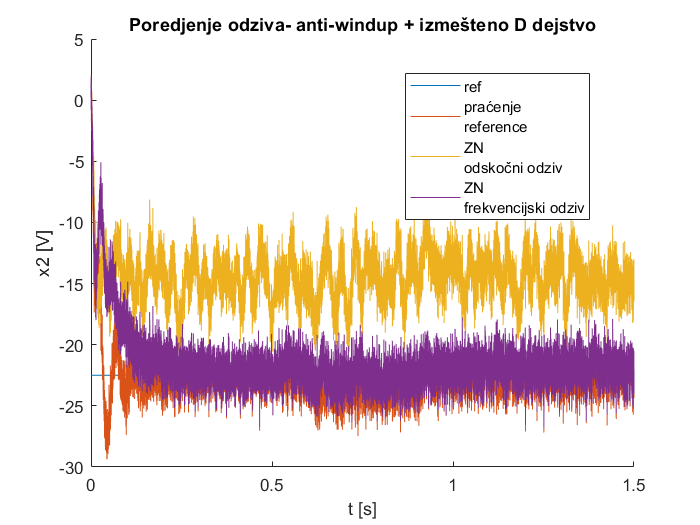

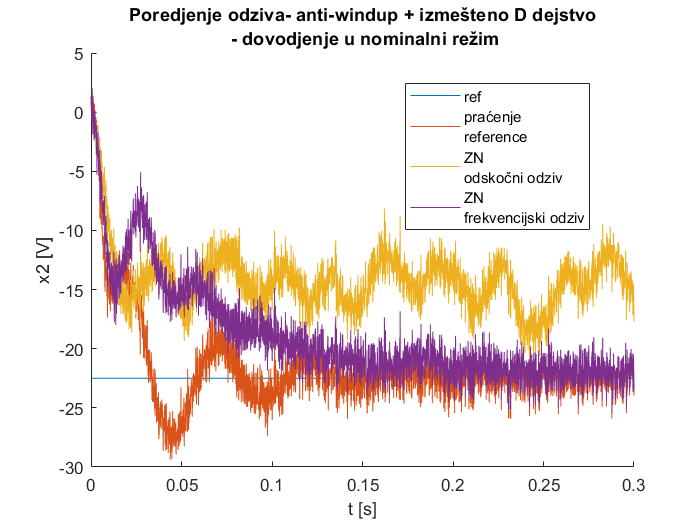

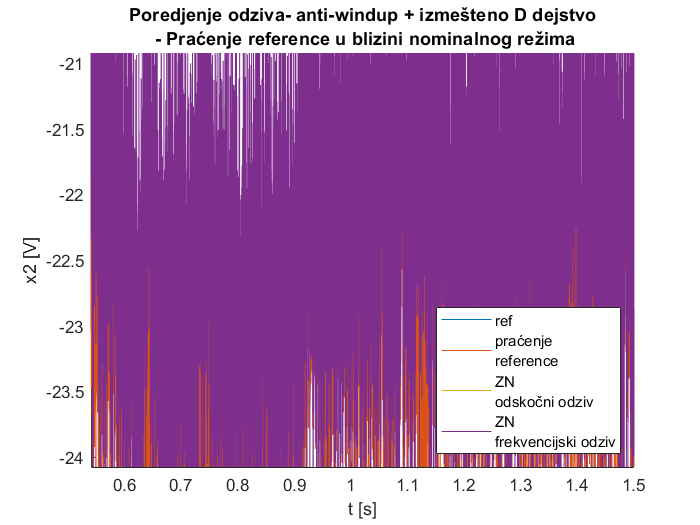

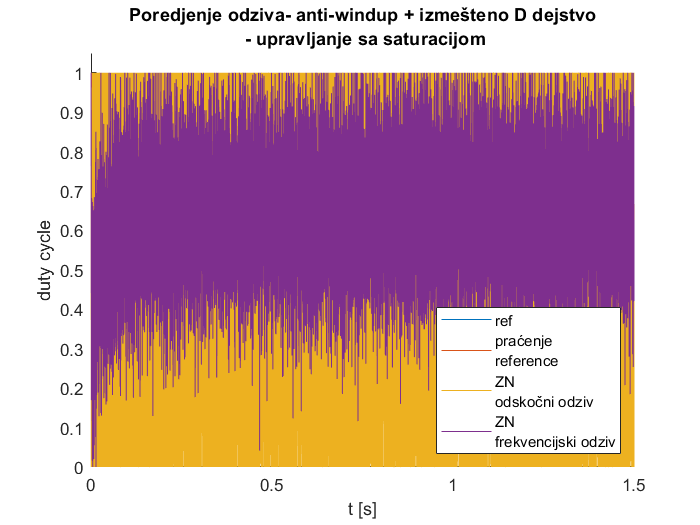

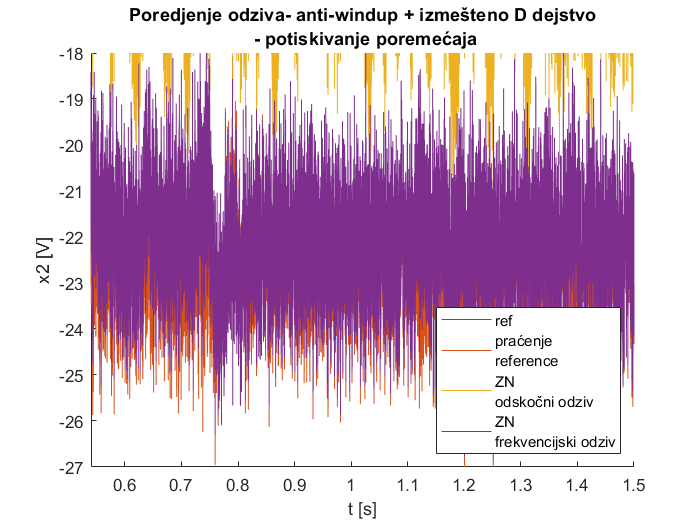

end